**Taller 11**

# **Invasión Zombie**

Esteban Mejía Buitrago

**Introducción**

El objetivo de este taller es resolver numéricamente, por el método numérico de Runge-Kutta implementado en la función [ode45](https://www.mathworks.com/help/matlab/ref/ode45.html) de MATLAB, la ecuación de estado de un modelo epidemiológico [SIRV](https://en.wikipedia.org/wiki/Compartmental_models_in_epidemiology#The_SIRV_model) (SIR con vacunados) no lineal en un archivo Live Script de MATLAB y analizar el resultado.

Modelo matemático

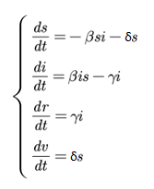

**Supuestos**: población cerrada (no llegan personas de otros lugares) y constante (*s* + *i* + *r* + *v* = 1), población uniforme, mezcla homogénea (sin consideraciones de edad, distribución espacial, educación o estructura social).

Donde, *s* es el porcentaje de personas susceptibles (pueden contraer la enfermedad), *i* es el porcentaje de personas infectadas, *r* es el porcentaje de personas recuperadas (y que no vuelven a contraer la enfermedad, es decir, quedan inmunes) y *v* es el porcentaje de personas vacunadas.

β es la tasa de transmisión, γ es la tasa de recuperación y aislamiento, y δ es la tasa de vacunación.

Observar que se tiene una epidemia creciente si (igual que en el caso SIR):

*R*0 es el número reproductivo básico.

Caso para estudiar (hay epidemia, *R*0 > 1): 

β = 0.1;

γ = 0.02; 

δ = 0.001; 

s(0) = 0.8; 

i(0) = 0.1; 

r(0) = 0;

v(0) = 0.1;

***Hicimos la verificación y si hay epidemia.***

**Actividades:**

- **Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones. ¿Cuál es el efecto de la vacunación? ¿Qué porcentaje mínimo de la población debe estar vacunada para que el pico de infectados se incremente sólo en un 50% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.15)?**

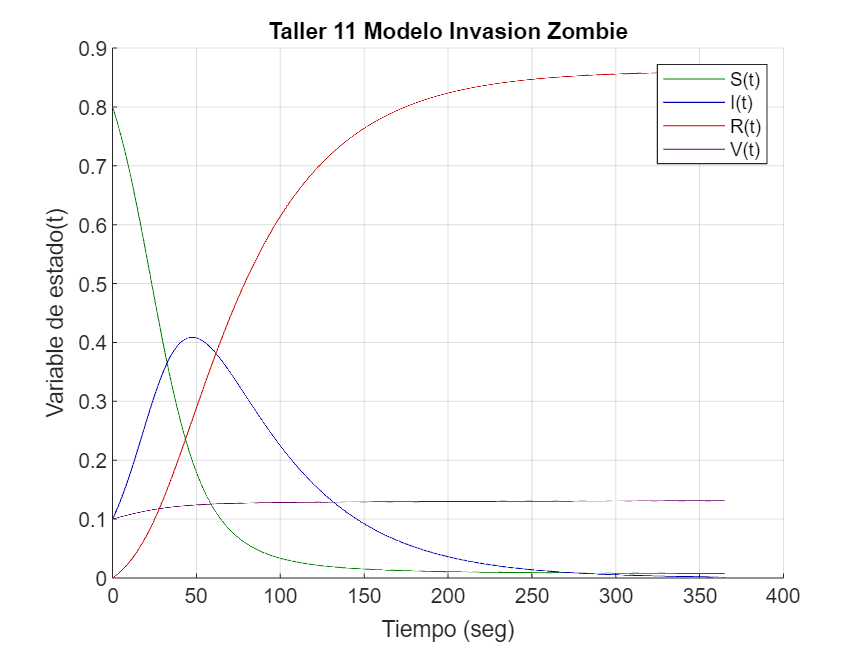

syms s(t) i(t) r(t) v(t)
beta = 0.1;
gamma = 0.02;
delta = 0.001;
eq1 = -beta*s*i-delta*s; %susceptibles (s)
eq2 = beta*s*i - gamma*i; %infectados (i)
eq3 = gamma*i; %recuperados (r)
eq4 = delta*s;
%Se usa el comando ODE45 para resolver
F = odeFunction ([eq1 eq2 eq3 eq4], [s i r v]);
%Tiempo
t0 = 0;
tf = 365;
%Paso
h = 0.1;
t = t0:h:tf;
%Condición inicial 
ci = [0.8 0.1 0 0.1];
%Resolver usando el comando ODE45
[t, sol] = ode45(F, t, ci);
s_sol = sol(:,1); %En una matriz todas las filas de la primera columna
i_sol = sol(:,2);
r_sol = sol(:,3);
v_sol = sol(:,4);
%Colores
color_verde = [0 0.5 0];
color_azul = [0 0 0.7];
color_rojo = [0.8 0 0];
color_morado = [0.4 0 0.4];
%Gráfica
figure 
hold on 
plot(t, s_sol, 'Color', color_verde(1,:))
plot(t, i_sol, 'Color', color_azul(1,:))
plot(t, r_sol, 'Color', color_rojo(1,:))
plot(t, v_sol, 'Color', color_morado(1,:))
xlabel('Tiempo (seg)')
ylabel ('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie')
legend('S(t)','I(t)','R(t)','V(t)')
grid on

# **Conclusiones **

**Resultados: **Se puede ver cómo el pico de personas infectadas llega hasta un 40% de la población y se nota que el crecimiento de los infectados junto con los vacunados esta relacionado con la disminucion de personas suceptibles. Tambien se evidencia que la población susceptible disminuye rapidamente hasta estabilizarse en un punto mientras que los vacunados aumenta gradualmente con el tiempo.

**Analisis: **Con el paso del tiempo se nota que la población susceptible disminuye, ya sea por infección o vacunación. La disminución es casi proporcional al aumento de los infectados más los vacunados. La curva de los vacunados crece lentamente debido a que la vacunación es muy baja (0.01) y solo el 10% se esta vacunando.

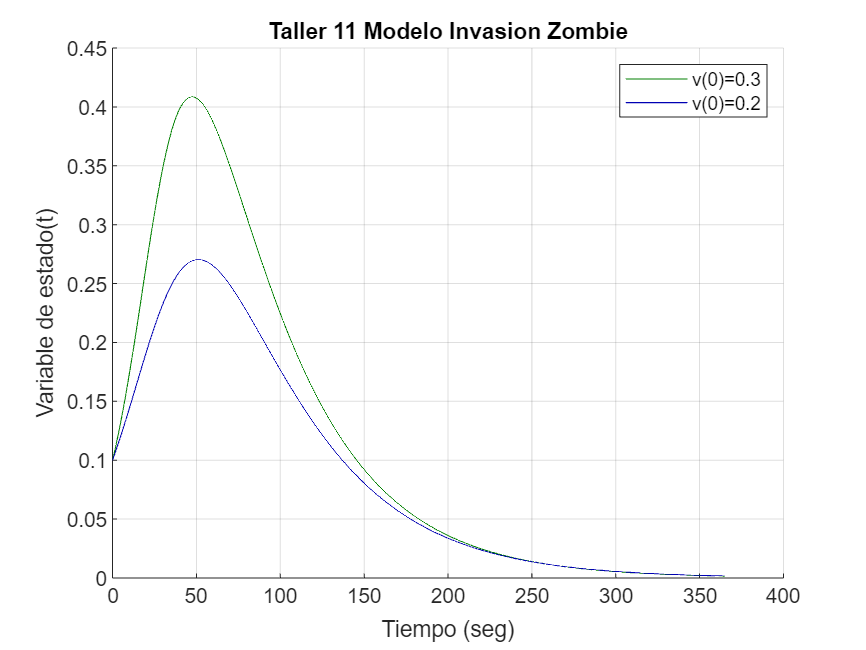

v0 = 0.3;
ci = [0.9-v0 0.1 0 v0];
[t2, sol] = ode45(F, t, ci);
i_sol2 = sol(:,2);
%Colores
color_verde = [0 0.5 0];
color_azul = [0 0 0.7];
figure
hold on
plot(t, i_sol, 'Color', color_verde(1,:))
plot(t2, i_sol2, 'Color', color_azul(1,:))
xlabel('Tiempo (seg)')
ylabel('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie')
grid on
legend({['v(0)=' num2str(v0)], 'v(0)=0.2'})

**Conclusiones **

**Resultados**: Se nota que la curva oscura llega a un pico que es casi de un 52% mayor que la verde clarita, con valores maximos de 0.41 (Verde oscura) y 0.27 (Verde clarita)

**Analisis: **Con forme aumenta la tasa de vacunación se logra ver que disminuyen los infectados, aunque las curvas de invfección tienen formas distintas se nota que el de recuperación es similar en ambas

**2.  Graficar sólo la solución *****i*****(*****t*****) con un aumento sólo de *****i*****(0) y usando al menos 5 valores. Observar que al cambiar *****i*****(0) cambia *****s*****(0), dado que la suma de todas las condiciones iniciales debe ser igual a 1. Interpretar los resultados.**

*Cambiamos condiciones inciales de los infectados zombies cuidando que mantengo en 1 el valor total de las condiciones inciales*

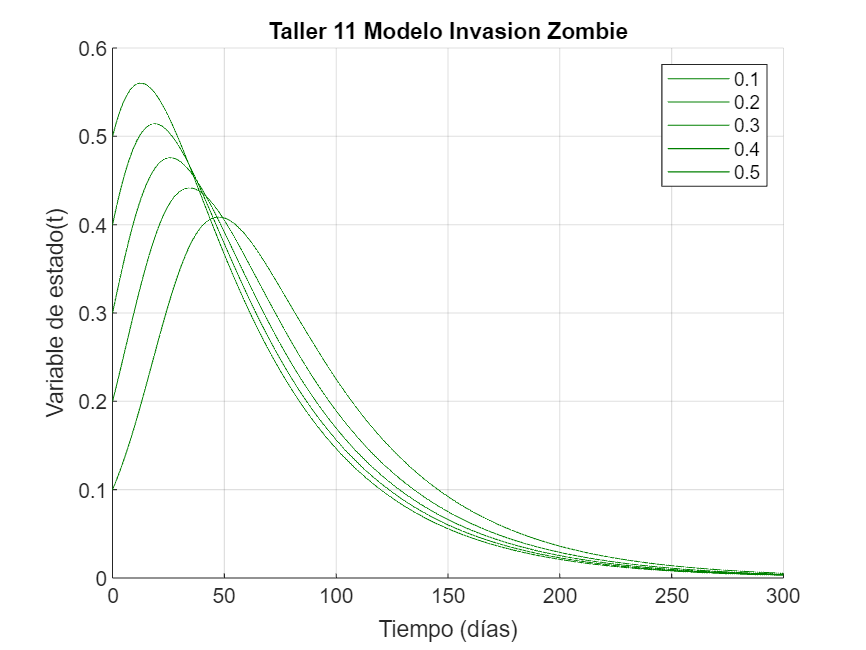

syms s(t) i(t) r(t) v(t)
beta = 0.1;
gamma = 0.02;
delta = 0.001;

eq1 = -beta*s*i-delta*s; % zombies suseptibles (s)
eq2 = beta*s*i - gamma*i; % zombies infectados (i)
eq3 = gamma*i; % zombies recuperados (r)
eq4 = delta*s; % zombies vacunados (v)

% Usamos el comando ODE45 para resolver
F = odeFunction ([eq1 eq2 eq3 eq4], [s i r v]);

% Tiempo
t0 = 0;
tf = 300;

% Paso
h = 0.1;
t = t0:h:tf;

% Condiciones iniciales múltiples
Multipleci = [0.8 0.1 0 0.1 % S I R V
              0.7 0.2 0 0.1
              0.6 0.3 0 0.1
              0.5 0.4 0 0.1
              0.4 0.5 0 0.1];

% Solución numérica
figure
hold on

%Colores
color_verde = [0 0.5 0];

for i = 1:size(Multipleci, 1)
    % Resolver usando el comando ODE45
    [t, sol] = ode45(F, t, Multipleci(i,:)); % con todas las variables de la matriz
    i_sol = sol(:,2); % En una matriz todas las filas de la segunda columna
    plot(t, i_sol, 'Color', color_verde(1,:))
end 

legend(num2str(Multipleci(:,2)))
xlabel('Tiempo (días)')
ylabel('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie')
grid on

**Conclusiones** 

**Resultados**: Al aumentar las personas infectadas el pico se vuelve más pronunciado en la grafica, y tambien es evidente que a medida que la curva crece el tiempo de recuperación tambien.

**Analisis**: Al usar una matriz comparativa para variar las condiciones iniciales de los infectados, susceptibles, recuperados y vacunados se observa que al comenzar con un valor mayor al de personas infectadas la curva se vuelve más pronunciada pero disminuyendo rapido, alcanzando su punto minimo alrededor de x=200.

**3. Graficar sólo la solución *****i*****(*****t*****) con un aumento sólo de β y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor máximo de beta (diferente de cero) se evitaría una epidemia? Interpretar los resultados.**

*Cambiamos la tasa de transmision*

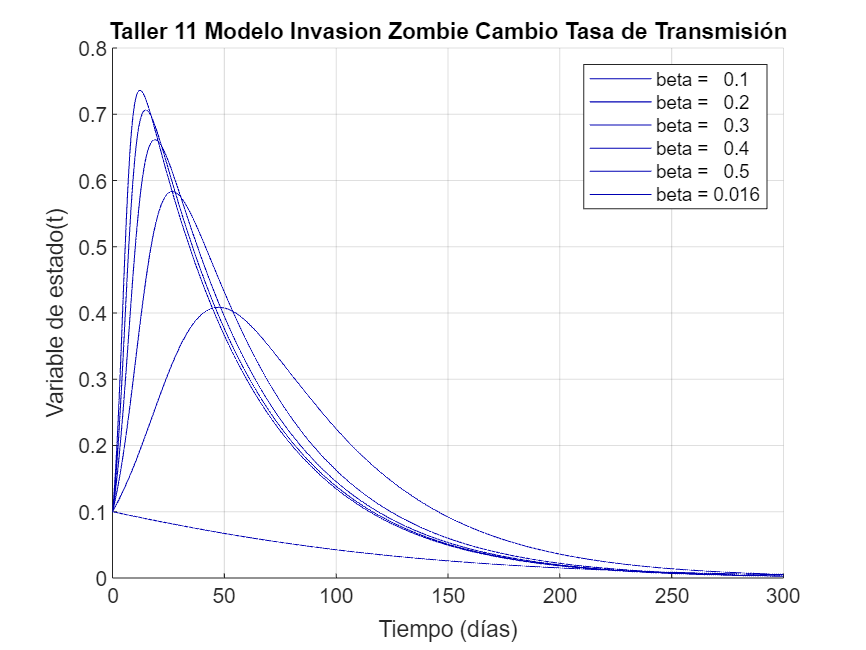

syms s(t) i(t) r(t) v(t)
beta =  [0.1 0.2 0.3 0.4 0.5 0.016];
gamma = 0.02;
delta = 0.001;

% Tiempo
t0 = 0;
tf = 300;

% Paso
h = 0.1;
t = t0:h:tf;

% Condición inicial
ci = [0.8 0.1 0 0.1];

% Solución numérica
figure
hold on

% Color
color_azul = [0 0 0.7];

for j = 1:length(beta)
    eq1 = -beta(j)*s*i-delta*s; % zombies Suseptibles (s)
    eq2 = beta(j)*s*i - gamma*i; % zombies Infectados (i)
    eq3 = gamma*i; % zombies Recuperados (r)
    eq4 = delta*s; % zombies Vacunados (v) 
    
    % Usamos el comando ODE45 para resolver
    F = odeFunction ([eq1 eq2 eq3 eq4], [s i r v]);
    % Resolver usando el comando ODE45
    [t, sol] = ode45(F, t, ci);
    i_sol = sol(:,2); % En una matriz todas las filas de la segunda columna
    plot(t, i_sol, 'Color', color_azul(1,:))
end 

legend("beta = " +  num2str(beta'))
xlabel('Tiempo (días)')
ylabel('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie Cambio Tasa de Transmisión')
grid on

**Conclusiones **

**Resultados**: Se ve que al aumentar el valor de beta el pico de la curva tambien se incrementa, ademas se nota que las más pronunciadas tienden a disminuir en un tiempo menor, tambien se destaca que la curva 0.016 no presenta ningun pico.

**Analisis: **El valor de 0.016 lo obtuvimos al despejar la formula ( ) y se utilizo como modelo, se puede ver que este valor no muentra pico en la grafica porque su valor inicial es menor a 0.1 el punto de inicio para las curvas en el modelo

**4. Graficar sólo la solución *****i*****(*****t*****) con un aumento sólo de γ y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor mínimo de γ se evitaría una epidemia? Interpretar los resultados.**

*Cambiamos la Tasa de recuperación*

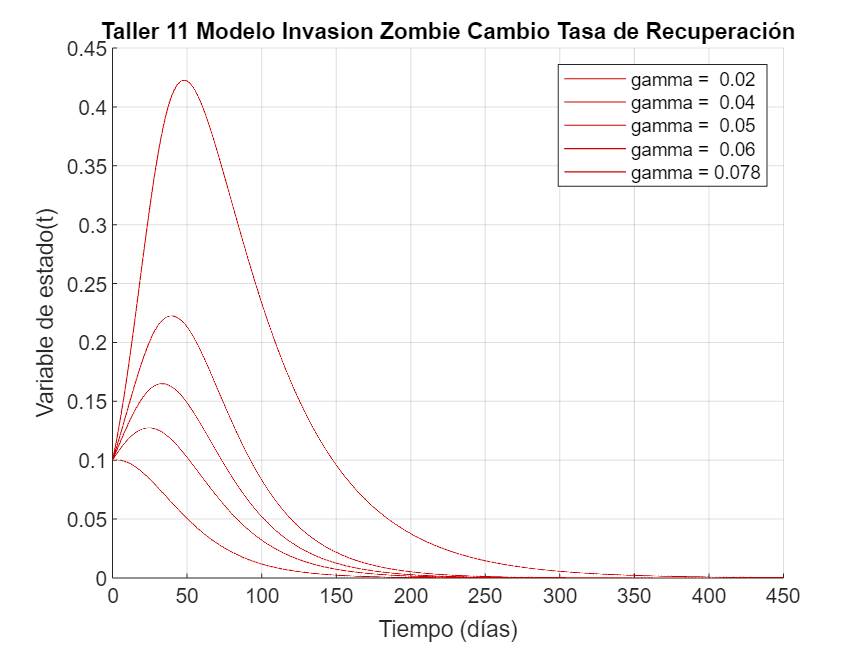

% Tasa de recuperacion
syms s(t) i(t) r(t) v(t)
beta = 0.1;
gamma = [0.02 0.04 0.05 0.06 0.078];
delta = 0.001;

% Tiempo
t0 = 0;
tf = 450;
h = 0.1;
t = t0:h:tf;

% Condición inicial
ci = [0.8 0.1 0 0.1];

% Solución numérica
figure
hold on

% Color
color_rojo = [0.8 0 0];

for idx = 1:length(gamma)
    gamma1 = gamma(idx);
    eq1 = -beta*s*i; % zombies Suseptibles (s)
    eq2 = beta*s*i - gamma1*i; % zombies Infectados (i)
    eq3 = gamma1*i; % zombies Recuperados (r)
    eq4 = delta*s; % zombies Vacunados (v) 
    
    % Usamos el comando ODE45 para resolver
    F = odeFunction([eq1 eq2 eq3 eq4], [s i r v]);
    % Resolver usando el comando ODE45
    [t, sol] = ode45(F, t, ci);
    i_sol = sol(:,2); % En una matriz todas las filas de la segunda columna
    plot(t, i_sol, 'Color', color_rojo(1,:))
end 

legend("gamma = " +  num2str(gamma'))
xlabel('Tiempo (días)')
ylabel('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie Cambio Tasa de Recuperación')
grid on

**Conclusiones** 

**Resultados**: En este caso se nota como al disminuir gamma el pico aumenta, tambien se ve que las curvas más pronunciadas necesitan más tiempo para estabilizarse.

**Analisis: **La curva de gamma =0.1 no presenta picos de infección ya que la tasa de recuperación es alta, a medida que gamma disminuye el pico de infección aumenta debido a que la tasa de recuperación más baja significa más infecciones. 0.078 se obtuvo al despejar  ()

**5. Graficar sólo la solución *****i*****(*****t*****) con un aumento sólo de δ y usando al menos 5 valores, uno de los cuales debe ser igual a cero. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con qué tasa mínima se debe vacunar la población de manera que el pico de infectados se incremente sólo en un 100% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.2)? Interpretar los resultados.**

*Cambiamos la tasa de reciperación*

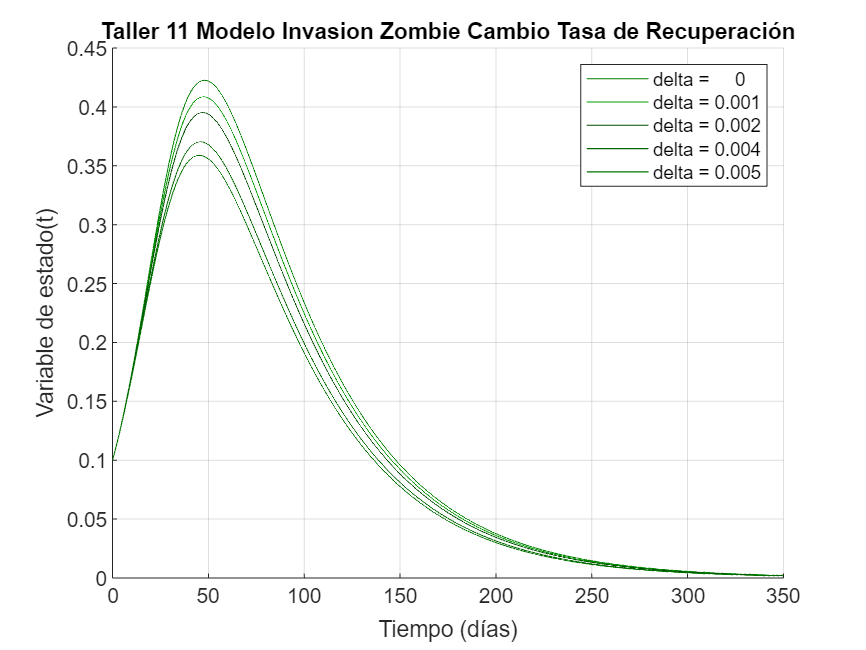

% Definición de variables.
syms s(t) i(t) r(t) v(t)

beta = 0.1; 
gamma = 0.02; 
delta = [0.00, 0.001, 0.002, 0.004, 0.005];

t0 = 0;
tf = 350;
h = 0.1;
t = t0:h:tf;

% Condición inicial.
ci = [0.8 0.1 0 0.1]; 

% Color morado
color_morado = [0.4 0 0.4];

% Gráfica
figure
hold on

for idx = 1:length(delta)
    delta1 = delta(idx);
    eq1 = -s*i*beta - delta1*s; % zombies Suseptible (s)
    eq2 = s*i*beta - gamma*i; % zombies Infectados (i)
    eq3 = gamma*i; % zombies Recuperados (r)
    eq4 = delta1*s; % Zombies Vacunados (v) 

    % Usamos el comando ODE45 para resolver
    F = odeFunction([eq1, eq2, eq3, eq4], [s i r v]);
    % Resolver usando el comando ODE45
    [t, sol] = ode45(F, t, ci); 

    i_sol = sol(:,2); % En una matriz todas las filas de la segunda columna
    plot(t, i_sol, 'Color', color_morado(1,:));
end 

legend("delta = " + num2str(delta'))
xlabel('Tiempo (días)')
ylabel('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie Cambio Tasa de Recuperación')
grid on

**Resultados: **Delta y el pico de infectados son inversamente proporcionales, esto significa que al delta disminuir, el pico tiene a aumentar.

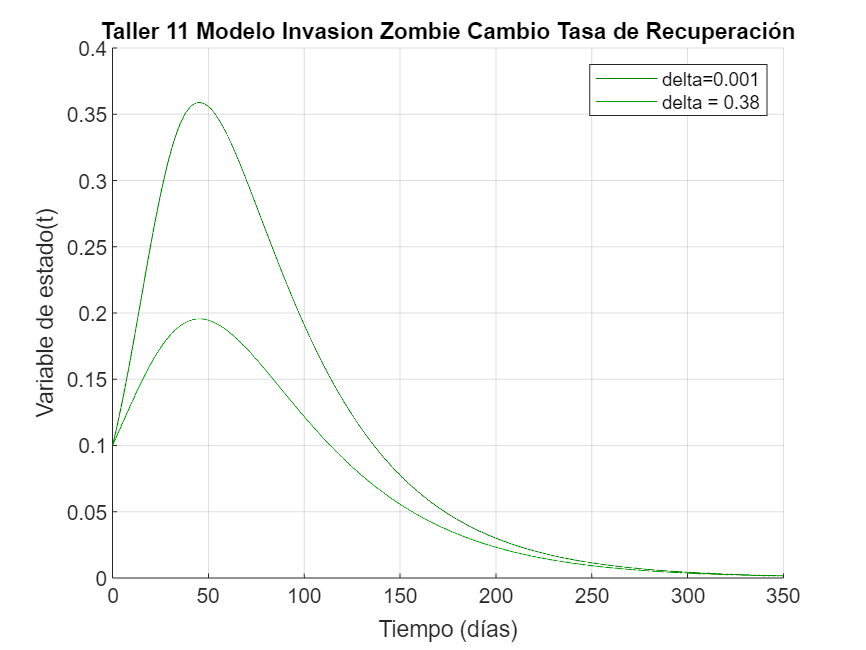

delta1 = 0.38;

% Condición inicial
ci = [0.9-delta1 0.1 0 v0]; 
[t2, sol2] = ode45(F, t, ci); 
i_sol2 = sol2(:,2); 

% Colores de verde
color_verde = [0 0.5 0];
color_morado = [0.4 0 0.4];

% Gráfica
figure
hold on
plot(t, i_sol, 'Color', color_verde(1,:))
plot(t2, i_sol2, 'Color', color_morado(1,:))
legend('delta=0.001', ['delta = ' num2str(delta1)])
xlabel('Tiempo (días)')
ylabel('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie Cambio Tasa de Recuperación')
grid on

**Conclusiones** 

**Resultados: **Las curvas en el grafico comienzan en y=0.1 similiar a los graficos anteriores, se nota que el valor de delta y el pico de infección mantienen una relación inversamente proporcionales, al igual que en el grafico anterior.

**Analisis: **A medida que aumenta el porcentaje de personas vacunadas, observamos una reducción en el porcentaje de personas infectadas. Esto es porque la tasa de vacunación ayuda a disminuir la propagación de la epidemia de zombies, ya que las personas vacunadas desarrollan inmunidad. Además, para lograr una reducción significativa del 50% en el pico de infectados en comparación con el valor inicial, se debe implementar una tasa de vacunación del 38%.